%------Jzobel----------------------------------------------------------------Jzobel--------------
%-------------------------------------TurboJ?^JMatlab?I,L1------------------------------
%------------------------------------------------------------------------------------------------
%This script simulates the classical turbo encoding-decoding system.
% It simulates parallel concatenated convolutional codes.
% Two component rate 1/2 RSC (Recursive Systematic Convolutional) component encoders are assumed.
% First encoder is terminated with tails bits. (Info + tail) bits are scrambled and passed to
% the second encoder, while second encoder is left open without tail bits of itself.
% -----------------------------------------------------------------------------------------------
% Random information bits are modulated into +1/-1, and transmitted through a AWGN channel.
% Interleavers are randomly generated for each frame?0?.
%------------------------------------------------------------------------------------------------
% Log-MAP algorithm without quantization or approximation is used.
% By making use of ln(e^x+e^y) = max(x,y) + ln(1+e^(-abs(x-y))),
% the Log-MAP can be simplified with a look-up table for the correction function.
% If use approximation ln(e^x+e^y) = max(x,y), it becomes MAX-Log-MAP.
%------------------------------------------------------------------------------------------------


% Frame size
L_total = input(' Please enter the frame size (= info + tail, default: 1024) ');
if isempty(L_total)
    L_total = 1024; % infomation bits plus tail bits
end
% Code generator
g = input(' Please enter code generator: ( default: g = [1 1 1; 1 0 1 ] ) ');
if isempty(g)
    g = [ 1 1 1;1 0 1 ];
end
% For example g = [1 1 0 1; 1 1 1 1];or g = [1 1 1 1 1; 1 0 0 0 1];
[n,K] = size(g); %返回矩阵g的行数和列数
m = K - 1; %尾随比特位数
nstates = 2^m;
%puncture = 0, puncturing into rate 1/2;
%puncture = 1, no puncturing（不删余）

puncture = input(' Please choose punctured / unpunctured (0/1): default 1 ');
if isempty(puncture)
    puncture = 1;
end

% Code rate
rate = 1/(2+puncture);
% Fading amplitude; a=1 in AWGN channel
a = 1;
% Number of iterations
niter = input(' Please enter number of iterations for each frame: default 3 ');
if isempty(niter)
    niter = 3;
end
% Number of frame errors to count as a stop criterior
ferrlim = input(' Please enter number of MonteCarlo: default 10 ');
if isempty(ferrlim)
    ferrlim = 10;
end
% Value of SNR db
EbN0db = input(' Please enter Eb/N0 in dB : default [0:0.25:5] ');
if isempty(EbN0db)
    EbN0db = 0:0.25:5;
end

fprintf('\n\n----------------------------------------------------\n');



----------------------------------------------------


fprintf(' Frame size = %6d\n',L_total);

 Frame size =   1024


fprintf(' code generator: \n');

 code generator: 


for i = 1:n
    for j = 1:K
        fprintf( '%6d', g(i,j));
    end
    fprintf('\n');
end

     1     1     1     1     0     1

if puncture==0
    fprintf(' Punctured, code rate = 1/2 \n');
else
    fprintf(' Unpunctured, code rate = 1/3 \n');
end

 Unpunctured, code rate = 1/3 


fprintf(' iteration number = %6d\n', niter);

 iteration number =      3


fprintf(' MonteCarlo numbers = %d\n', ferrlim);

 terminate frame errors = 10


fprintf(' Eb / N0 (dB) = ');

 Eb / N0 (dB) = 


for i = 1:length(EbN0db)
    fprintf('%10.2f',EbN0db(i));
end

      0.00      0.25      0.50      0.75      1.00      1.25      1.50      1.75      2.00      2.25      2.50      2.75      3.00      3.25      3.50      3.75      4.00      4.25      4.50      4.75      5.00

fprintf('\n----------------------------------------------------\n\n');


----------------------------------------------------



fprintf('+ + + + Please be patient. Wait a while to get the result. + + + +\n\n');

+ + + + Please be patient. Wait a while to get the result. + + + +




ber=zeros(length(EbN0db),niter);
for nEN = 1:length(EbN0db)
    en = 10^(EbN0db(nEN)/10); % convert Eb/N0 from unit db to normal numbers
    L_c = 4*a*en*rate; % reliability value of the channel
    sigma = 1/sqrt(2*rate*en); % standard deviation of AWGN noise
    % Clear bit error counter and frame error counter
    errs(nEN,1:niter) = zeros(1,niter);
    nferr(nEN,1:niter) = zeros(1,niter);
    sum(1:niter) = zeros(1,niter);
    nframe(nEN,1) = 0; % clear counter of transmitted frames
    while nframe(nEN,1)<ferrlim
        nframe(nEN,1) = nframe(nEN,1) + 1;
        errs(nEN,1:niter) = zeros(1,niter);
        err(1:niter) = zeros(1,niter);
        for k = 1:5
            err(1:niter) = zeros(1,niter);
            x = round(rand(1, L_total-m)); % info. bits
            [temp, alpha] = sort(rand(1,L_total)); % random interleaver mapping(排序，索引-alpha)
            en_output = encoderm(x, g, alpha, puncture) ; % encoder output (+1/-1)
            r = en_output+sigma*randn(1,L_total*(2+puncture)); % received bits
%            demodulated = gmsk_demod(r);
            yk = demultiplex(r,alpha,puncture); % demultiplex to get input for decoder 1 and 2
            
            % Scale the received bits
            rec_s = 0.5*L_c*yk;
            % Initialize extrinsic information
            L_e = zeros(1,L_total);
            L_a = zeros(1,L_total);
            for iter = 1:niter
                % Decoder one
                % deinterleave the extrinsic information for first decoder
                L_a(alpha) = L_e; % a priori info.
                L_all = log_map(rec_s(1,:), g, L_a, 1); % complete info.
                L_e = L_all - 2*rec_s(1,1:2:2*L_total) - L_a; % extrinsic info.
                % Decoder two
                L_a = L_e(alpha); % a priori info.
                L_all = log_map(rec_s(2,:), g, L_a, 2); % complete info.               
                L_e = L_all - 2*rec_s(2,1:2:2*L_total) - L_a; % extrinsic info.
                % Estimate the info. bits
                xhat(alpha) = (sign(L_all)+1)/2;
                % Number of bit errors in current iteration
                err(iter) = length(find(xhat(1:L_total-m)~=x));
                if err(iter)>0
                    nferr(nEN,iter) = nferr(nEN,iter)+1;
                end
            end %iter
            % Total number of bit errors for all iterations
        errs(nEN,1:niter) = errs(nEN,1:niter) + err(1:niter);
        end
        sum(1:niter) =sum(1:niter)+ errs(nEN,1:niter)/5/(L_total-m);
                
    end %while
    ber(nEN,1:niter) = sum(1:niter)/ferrlim;
    fprintf('%d',nEN); 
end %nEN

123456789101112131415161718192021

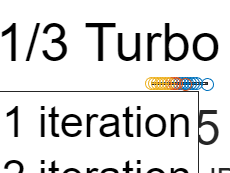

semilogy(EbN0db,ber,'-o')
legend('1 iteration','2 iteration','3 iteration')
title('1/3 Turbo code ')
set(gca,'FontSize',24)
xlabel('SNR/dB','FontSize',16);
ylabel('BER','FontSize',16);
grid on;